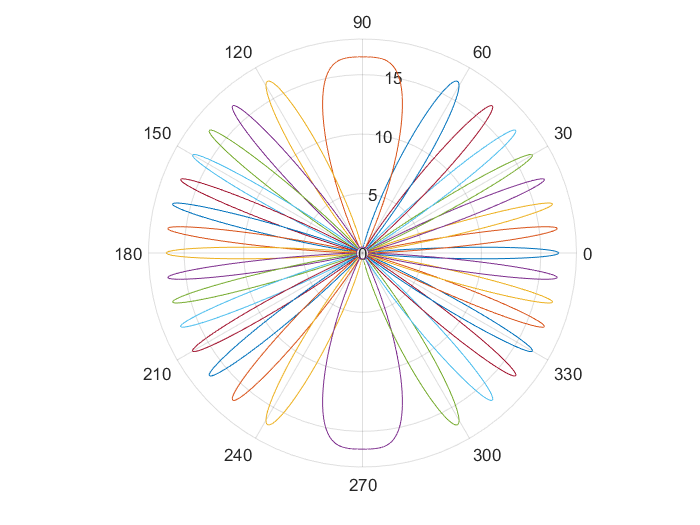

global Cliq Cliqend IF_Graph Res
global Link Node IFLink AP TimeStandard TimeLength Scheme Availability RFUsage
close all;
Nt=16;
b=0:2*Nt-1;
I=(b>=Nt/2 & b<=3/2*Nt-1);
f=(-b+3*Nt).*I+b.*~I;
p0=0.5;
dtheta=pi/10000;
theta=(0:dtheta:2*pi-dtheta).';
thetam=asin(mod(2*f/Nt,2)-2*(mod(2*f/Nt,2)>1));
thetam(Nt/2+2:3*Nt/2)=pi-thetam(Nt/2+2:3*Nt/2);
thetam(3*Nt/2+1)=thetam(3*Nt/2+1)+pi;
thetam(3*Nt/2+2:end)=2*pi+thetam(3*Nt/2+2:end);
thetatop=[thetam(2:end),thetam(1)+2*pi];
thetabottom=[thetam(end)-2*pi,thetam(1:end-1)];
G=1/Nt*(sin(Nt*pi/2*(sin(theta)-2*f/Nt))./sin(pi/2*(sin(theta)-2*f/Nt))).^2 ...
    .*[theta>thetabottom(1)+2*pi | theta<thetatop(1),theta<thetatop(2:end) & theta>thetabottom(2:end)]...
    +p0;
for i=1:size(G,2)
    polarplot(theta,G(:,i));
    hold on
end
hold off

option_linprog = optimoptions(@linprog,'Display','off','Diagnostics','off');
option_quadprog = optimoptions(@quadprog,'Display','off','Diagnostics','off');

预存储

APNum=10;
BS_RFNum=4;
AP_RFNum_In=2;
AP_RFNum_Out=4;
SimNum=100;
bvec=d*[...
    0+1i/sqrt(3),1/2+1i/2/sqrt(3);
    1/2+1i/2/sqrt(3),1/2-1i/2/sqrt(3);
    1/2-1i/2/sqrt(3),0-1i/sqrt(3);
    0-1i/sqrt(3),-1/2-1i/2/sqrt(3);
    -1/2-1i/2/sqrt(3),-1/2+1i/2/sqrt(3);
    -1/2+1i/2/sqrt(3),0+1i/sqrt(3)
    ];
Res=400;FrameNum=6;
for UserNum=50:10:120
mkdir("Network1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out));
for Sim=1:SimNum
%生成AP坐标------------------------------------------
d = 200;%单位距离m
APPosition = [...
    0, 0;...
    d/2, -sqrt(3)/2*d;...
    d, 0;...
    d/2, sqrt(3)/2*d;...
    3/2*d, -sqrt(3)/2*d;...
    2*d, 0;...
    3/2*d, sqrt(3)/2*d;...
    5/2*d, -sqrt(3)/2*d;...
    3*d, 0;...
    5/2*d, sqrt(3)/2*d];
APPosition=APPosition(1:APNum,:);
APPosition = APPosition(:,1) + 1j * APPosition(:,2);

%生成用户坐标，约束在某个范围内-----------------------------------------------
t1=randi(APNum,[UserNum,1]);
t2=randi(6,[UserNum,1]);
tx=rand([UserNum,1]);
ty=rand([UserNum,1]);
I=tx+ty>1;
tx(I)=1-tx(I);
ty(I)=1-ty(I);
UserPosition=APPosition(t1)+sum(bvec(t2,:).*[tx,ty],2);
Demand=rand([UserNum,1]);
save("Network1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out)+"\"...
    +num2str(Sim)+".mat","APPosition","UserPosition","Demand");
end
end

Record=table(zeros(SimNum,1),zeros(SimNum,1),zeros(SimNum,1),zeros(SimNum,1),...
    'VariableNames',{'LP','QP','HP','LB'});

使用RL方法求解

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0011    0.0000    0.0870    0.0002    0.0017    0.0018    0.0010    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0004    0.0001    0.1134    0.0014    0.0003    0.0001    0.0002    0.0000    0.0123    0.0018    0.0000    0.0005    0.0001    0.0001    0.0002    0.0003    0.0000    0.0001    0.0001    0.0001    0.0124    0.0071    0.0001    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0000    0.0003    0.0000    0.0001    0.0002    0.0025    0.0000    0.0002    0.0001    0.0003    0.0001    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0003    0.0014    0.0002    0.0001    0.0012    0.0000    0.0007    0.0002    0.0000    0.0031    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0001    0.0003    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0001    0.0041    0.0000    0.0008    0.0002    0.0007    0.0002    0.0002    0.0000    0.0123    0.0001    0.0003    0.0001    0.0001    0.0006    0.0010    0.0006    0.0005    0.0112    0.0000    0.0001    0.0012    0.0003    0.0000    0.0150    0.0004    0.0017    0.0010    0.0000    0.0002    0.0002    0.0000    0.0002    0.0001    0.0007    0.0007    0.0007    0.0001    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0002    0.0001    0.0007    0.0000    0.0001    0.0002    0.0001    0.0004    0.0000    0.0000    0.0003    0.0000    0.0008    0.0000    0.0000    0.0080    0.0001    0.0002    0.0094    0.0017    0.0000    0.0001    0.0001    0.0001    0.0000    0.0002    0.0001    0.0030    0.0001    0.0000    0.0002    0.0001    0.0001    0.0001    0.0000    0.0003    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0002    0.0020    0.0000    0.0001    0.0002    0.0000    0.0029    0.0137    0.0008    0.0013    0.0675    0.0005    0.0001    0.0004    0.0147    0.0009    0.0002    0.0041    0.0736    0.0105    0.0017    0.0009    0.0001    0.0001    0.0000    0.0000    0.0017    0.0001    0.0001    0.0001    0.0000    0.0010    0.0000    0.0001    0.0007    0.0146    0.0001    0.0000    0.0003    0.0011
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0004    0.0014    0.0002    0.0042    0.0005    0.0001    0.0000    0.0005    0.0001    0.0618    0.0000    0.0002    0.0004    0.0008    0.0063    0.0622    0.0000    0.0001    0.0000    0.0000    0.0531    0.0001    0.0001    0.0000    0.0000    0.0002    0.0000    0.0001    0.0001    0.0005    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0002    0.0001    0.0001    0.0004    0.0002    0.0005    0.0001    0.0002    0.0006    0.0000    0.0005    0.0013    0.0190    0.0000    0.0006    0.0000    0.0001    0.0010    0.0004    0.0000    0.0003    0.0007    0.0002    0.0005    0.0000    0.0001    0.0001    0.0000    0.0000    0.0007    0.0000    0.0002    0.0004    0.0008    0.0000    0.0007    0.0000    0.0009    0.0005    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0003    0.0001    0.0000    0.0001    0.0001    0.0005    0.0001    0.0000    0.0001    0.0000    0.0007    0.0079    0.0007    0.0000    0.0002    0.0000    0.0000    0.0022    0.0027    0.0001    0.0001    0.0008    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0359    0.0001    0.0001    0.0000    0.0047    0.0000    0.0001    0.0001    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0047    0.0000    0.0000    0.0015    0.0000    0.0000    0.0000    0.0000    0.0018    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0107    0.0000    0.0001    0.0016    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0002    0.0000    0.0000    0.0000
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0003    0.0000    0.0000    0.0001    0.0000    0.0009    0.0000    0.0001    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0008    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0005    0.0002    0.0000    0.0004    0.0000    0.0003    0.0012    0.0000    0.0001    0.0004    0.0000    0.0010    0.0002    0.0003    0.0001    0.1133    0.0000    0.0001    0.0002    0.0422    0.0000    0.0109    0.0003    0.0003    0.0159    0.0008    0.4752    0.0000    0.0004    0.0084    0.0073    0.0000    0.0003    0.0016    0.0001    0.0068    0.0003    0.0005    0.0001    0.0034
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0033    0.0001    0.0000    0.0017    0.0000    0.0004    0.0185    0.0000    0.0001    0.0005    0.0000    0.0149    0.0005    0.0058    0.0000    0.0005    0.0000    0.0001    0.0001    0.0004    0.0000    0.0002    0.0006    0.0004    0.0005    0.0001    0.0007    0.0000    0.0001    0.0002    0.0001    0.0000    0.0002    0.5649    0.0001    0.0001    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0011    0.0000    0.0001    0.0002    0.0011    0.0000    0.0001    0.0024    0.0001    0.0000    0.0009    0.0002    0.0035    0.0001    0.0003    0.0000    0.0009    0.0028    0.0007    0.0003    0.0001    0.0000    0.0002    0.0011    0.0002    0.0001    0.0005    0.0001    0.0010    0.0000    0.0002    0.0003    0.0005    0.0078    0.0000    0.0003    0.0000    0.0001    0.0001    0.0003
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0030    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0088    0.0002    0.0001    0.0458    0.0004    0.0007    0.0000    0.0007    0.0000    0.0001    0.0002    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0002    0.0000    0.0002    0.0002    0.0039    0.0000    0.0002    0.0010    0.0001    0.0015    0.0000    0.0003    0.0001    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0002    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0001    0.0001    0.0000    0.0001    0.0014    0.0001    0.0001    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0008    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0005
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0005    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0063    0.0002    0.0000    0.0004    0.0000    0.0001    0.0015    0.0000    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0000    0.0000    0.0000    0.0001    0.0000    0.0002    0.0003    0.0002    0.0004    0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0002    0.0044    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0024    0.0000    0.0004    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0023    0.0000    0.0000    0.0000    0.0003
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0013    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0008    0.0000    0.0000    0.0001    0.0005    0.0000    0.0000    0.0000    0.0000    0.0002    0.0001    0.0000    0.0000    0.0000    0.0003    0.0000    0.0001    0.0000    0.0003    0.0000    0.0001    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0000    0.0003    0.0001    0.0002    0.0000    0.0015    0.0004    0.0000    0.0057    0.0001    0.0012    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0001    0.0000    0.0001    0.0000    0.0001    0.0004    0.0000    0.0000    0.0029    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0000    0.0010    0.0000    0.0003    0.0000    0.0001    0.0000    0.0000    0.0001    0.0023    0.0000    0.0000    0.0000    0.0030    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0013    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0001    0.0013    0.0001    0.0000    0.0010    0.0001    0.0003    0.0007    0.0008    0.0001    0.0011    0.0002    0.0003    0.0000    0.0000    0.0002    0.0000    0.0005    0.0001    0.0000    0.0003    0.0001    0.0019    0.0173    0.0005    0.0003    0.0008    0.0022    0.0068    0.0000    0.0002    0.0001    0.0000    0.0028    0.0028    0.0001    0.0001    0.0001    0.0003
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0002    0.0002    0.0001    0.0000    0.0000    0.0006    0.0002    0.0001    0.0053    0.0001    0.0003    0.1194    0.0006    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0018    0.0003    0.0022    0.0001    0.0020    0.0181    0.0003    0.0000    0.0001    0.0001    0.0000    0.0068    0.0069    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0000    0.0025    0.0001    0.0000    0.0004    0.0000    0.0003    0.0008    0.0000    0.0002    0.0002    0.0007    0.0000    0.0001    0.0011    0.0001    0.0009    0.0000    0.0002    0.0000    0.0002    0.0000    0.0004    0.0000    0.0012    0.0005    0.0001    0.0008    0.0009    0.0000    0.0003    0.0000    0.0015    0.0048    0.0001    0.0002    0.0001    0.0093    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0000    0.0003    0.0001    0.0000    0.0016    0.0001    0.0002    0.0074    0.0000    0.0001    0.0001    0.0001    0.0000    0.0001    0.0002    0.0000    0.0002    0.0000    0.0008    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0029    0.0000    0.0018    0.0001    0.0000    0.0001    0.0000    0.0001    0.0033    0.0001    0.0001    0.

ADJChart = 	1.0e+-8 *

         0    0.4853    0.5017    0.4853    0.0973         0    0.0973         0         0         0    0.6069    0.0013    0.0601    0.0113    0.0019    0.0010    0.0013    0.0776    0.0004    0.0025    0.0004    0.0005    0.0023    0.0012    0.0881    0.0386    0.0378    0.0047    0.0002    0.0012    0.0284    0.0002    0.0010    0.2920    0.0086    0.0067    0.0009    0.0016    0.0024    0.0004    0.0007    0.0517    0.0114    0.2776    0.0100    0.0142    0.0036    0.0005    0.0008    0.0005
         0         0    0.1941         0    0.2007         0         0         0         0         0    0.0089    0.0090    0.0030    0.0007    0.0005    0.0004    0.0020    0.0021    0.0002    0.0035    0.0001    0.0003    0.0043    0.0022    0.0015    0.0028    0.0483    0.0005    0.0002    0.0005    0.0161    0.0002    0.0006    0.0126    0.1574    0.0010    0.0002    0.0016    0.0005    0.0001    0.0004    0.0020    0.0126    0.0109    0.0147    0.0600    0.0008    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0245    0.0002    0.0001    0.0168    0.0007    0.0005    0.0002    0.0006    0.0002    0.0014    0.0005    0.0001    0.0003    0.0002    0.0004    0.0002    0.0009    0.0008    0.0004    0.0001    0.0004    0.0001    0.0034    0.0000    0.0013    0.0009    0.0004    0.0000    0.0001    0.0002    0.0001    0.0014    0.0938    0.0001    0.0049    0.0094    0.0003    0.0001    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0006    0.0002    0.0000    0.0002    0.0008    0.0007    0.0004    0.0082    0.0001    0.0026    0.0006    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0022    0.0007    0.0002    0.0008    0.0001    0.0098    0.0000    0.0008    0.0463    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0005    0.0000    0.0022    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0007    0.0010    0.0001    0.0047    0.1575    0.0020    0.0004    0.0177    0.0006    0.0344    0.0010    0.0000    0.0006    0.0000    0.0668    0.0104    0.0001    0.0010    0.0000    0.0011    0.0003    0.0064    0.0003    0.0001    0.0001    0.0010    0.0002    0.0002    0.0075    0.0000    0.0001    0.0000    0.0002    0.0001    0.0002    0.0066    0.0003    0.0077    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0044    0.0003    0.0001    0.0027    0.0007    0.0001    0.0016    0.0008    0.0002    0.0006    0.0911    0.0000    0.0005    0.0000    0.0007    0.0002    0.0002    0.0003    0.0000    0.0001    0.0042    0.0002    0.0002    0.0000    0.0000    0.0014    0.0001    0.0000    0.0007    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001    0.0017    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0001    0.0000    0.0004    0.0003    0.0005    0.0000    0.0608    0.0001    0.0005    0.0028    0.0000    0.0417    0.0001    0.0003    0.0000    0.0009    0.1224    0.0005    0.0005    0.0006    0.0000    0.0001    0.0408    0.0004    0.0060    0.0002    0.0005    0.0043    0.0000    0.0004    0.0000    0.0002    0.0001    0.0003    0.0082    0.0056    0.0001    0.0002    0.0009
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0001    0.0000    0.0001    0.0002    0.0004    0.0001    0.0010    0.0004    0.0006    0.0004    0.0000    0.0002    0.0000    0.0043    0.0000    0.0034    0.0003    0.0001    0.0002    0.0001    0.0000    0.0001    0.0009    0.0006    0.0026    0.0002    0.0005    0.0053    0.0000    0.0001    0.0000    0.0001    0.0000    0.0009    0.0006    0.0016    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0001    0.0001    0.0000    0.0002    0.0002    0.0000    0.0007    0.0001    0.0012    0.0002    0.0029    0.0079    0.0001    0.0017    0.0000    0.0001    0.0004    0.0001    0.0000    0.0000    0.0021    0.0000    0.0001    0.0000    0.0001    0.0008    0.0003    0.0086    0.0000    0.0001    0.0000    0.0013    0.0001    0.0018    0.0001    0.0009    0.0000    0.0002    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0001    0.0002    0.0000    0.0004    0.0002    0.0000    0.0176    0.0000    0.0051    0.0001    0.0043    0.0004    0.0001    0.0001    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0003    0.0000    0.0001    0.0000    0.0001    0.0022    0.0001    0.0004    0.0000    0.0002    0.0000    0.0002    0.0000    0.0035    0.0003    0.0001    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0002    0.0002    0.0000    0.0001    0.0000    0.0000
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0022    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5323    0.0000    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0002    0.0000    0.0001    0.0000    0.0003    0.0006    0.0021    0.0014    0.0000    0.0001    0.0009    0.0000    0.0001    0.0006    0.0000    0.0003    0.0001    0.0005    0.0000    0.0081    0.0005    0.0001    0.0000    0.0011    0.0006    0.0000    0.0000    0.0008    0.0012    0.0033    0.0003    0.0133    0.0022    0.0005    0.0005    0.0000    0.0037    0.0000    0.0031    0.0040
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0000    0.0003    0.0001    0.0003    0.0001    0.0081    0.0002    0.0000    0.0000    0.0002    0.0000    0.0000    0.0001    0.0000    0.0002    0.0001    0.0021    0.0000    0.0002    0.0001    0.0000    0.0000    0.0001    0.0015    0.0000    0.0000    0.0001    0.0043    0.0007    0.0003    0.0009    0.0003    0.0000    0.0002    0.0000    0.0009    0.

ADJChart = 	1.0e+-8 *

         0    0.4853    0.5017    0.4853    0.0973         0    0.0973         0         0         0    0.0009    0.0005    0.0004    0.0004    0.0057    0.0221    0.0161    0.7211    0.0005    0.0006    0.0206    0.0103    0.0002    0.0014    0.0015    0.0001    0.0184    0.0007    0.0008    0.0010    0.0033    0.0037    0.0008    0.0068    0.0432    0.0113    0.1505    0.0005    0.0048    0.0029    0.0056    0.0119    0.0425    0.0009    0.2453    0.0008    0.0003    0.0008    0.0003    0.0308
         0         0    0.1941         0    0.2007         0         0         0         0         0    0.0003    0.0003    0.0005    0.0001    0.0008    0.0374    0.0010    0.0058    0.0004    0.0004    0.0017    0.0010    0.0001    0.0004    0.0008    0.0001    0.0032    0.0004    0.0007    0.0004    0.0036    0.0068    0.0012    0.0033    0.0045    0.0015    0.0078    0.0003    0.0206    0.0173    0.0007    0.0011    0.0103    0.0025    0.0014    0.0003    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0002    0.0001    0.0006    0.0002    0.0108    0.0002    0.0007    0.0002    0.0023    0.0015    0.0001    0.0007    0.0001    0.0001    0.0000    0.0016    0.0025    0.0001    0.0004    0.0049    0.0000    0.0010    0.0001    0.0006    0.0003    0.0001    0.0138    0.0003    0.0032    0.0071    0.0006    0.0168    0.0000    0.0012    0.0000    0.0021    0.0017    0.0001    0.0000    0.0002
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0004    0.0001    0.0002    0.0001    0.0004    0.0001    0.0012    0.0006    0.0131    0.0029    0.0000    0.0002    0.0000    0.0000    0.0000    0.0156    0.0187    0.0000    0.0027    0.0002    0.0000    0.0003    0.0000    0.0004    0.0004    0.0001    0.0010    0.0001    0.0030    0.0009    0.0001    0.0005    0.0000    0.0012    0.0000    0.0033    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0070    0.0018    0.0001    0.0003    0.0000    0.0004    0.0004    0.0088    0.0002    0.0034    0.0002    0.0001    0.0026    0.0001    0.0001    0.0127    0.0032    0.0001    0.0002    0.0003    0.0003    0.0003    0.0003    0.0002    0.0000    0.0000    0.0050    0.0005    0.0001    0.0002    0.0001    0.0000    0.0003    0.0000    0.0001    0.0001    0.0001    0.0027    0.0025    0.0011
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0002    0.0007    0.0000    0.0001    0.0000    0.0003    0.0002    0.0008    0.0029    0.0021    0.0001    0.0000    0.0126    0.0000    0.0000    0.0002    0.0002    0.0000    0.0001    0.0000    0.0055    0.0005    0.0018    0.0003    0.0000    0.0000    0.0006    0.0001    0.0001    0.0002    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0239    0.0000    0.0007    0.0001    0.0004    0.0004    0.0000    0.0010    0.0009    0.0000    0.0000    0.0000    0.0001    0.0014    0.0078    0.0536    0.0003    0.0003    0.0002    0.0705    0.0000    0.0010    0.0014    0.0005    0.0062    0.0004    0.0107    0.0107    0.0007    0.0001    0.0001    0.0047    0.0001    0.0120    0.0000    0.0002    0.0016    0.0001    0.0029
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0009    0.0001    0.0013    0.0000    0.0003    0.0013    0.0000    0.0001    0.0003    0.0000    0.0000    0.0000    0.0000    0.0077    0.0002    0.0003    0.0001    0.0001    0.0001    0.0003    0.0000    0.0002    0.0337    0.0002    0.0002    0.0001    0.0001    0.0019    0.0001    0.0000    0.0000    0.0004    0.0002    0.0004    0.0000    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0014    0.0001    0.0241    0.0001    0.0001    0.0000    0.0012    0.0077    0.0000    0.0006    0.0003    0.0000    0.0004    0.0002    0.0001    0.0006    0.0002    0.0009    0.0004    0.0001    0.0054    0.0001    0.0022    0.0001    0.0001    0.0000    0.0008    0.0017    0.0001    0.0010    0.0085    0.0003    0.0001    0.0000    0.0001    0.0000    0.0005    0.0001    0.0098
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0092    0.0001    0.0005    0.0001    0.0000    0.0001    0.0002    0.0004    0.0000    0.0001    0.0005    0.0000    0.0025    0.0002    0.0001    0.0001    0.0003    0.0034    0.0001    0.0002    0.0001    0.0000    0.0004    0.0000    0.0001    0.0001    0.0007    0.0001    0.0000    0.0030    0.0009    0.0001    0.0001    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0001    0.0001    0.0000    0.0007    0.0027    0.0006    0.0003    0.0001    0.0002    0.0002    0.0087    0.0000    0.0042    0.0001    0.0001    0.0001    0.0011    0.0000    0.0006    0.0001    0.0079    0.0000    0.0006    0.0016    0.0000    0.0006    0.0056    0.0001    0.0000    0.0003    0.0017    0.0001    0.0001    0.0001    0.0007    0.0035    0.0001    0.0010    0.0002
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0001    0.0000    0.0000    0.0003    0.0002    0.0001    0.0008    0.0000    0.0001    0.0016    0.0009    0.0000    0.0039    0.0001    0.0002    0.0000    0.0006    0.0000    0.0162    0.0000    0.0018    0.0001    0.0001    0.4805    0.0000    0.0002    0.0014    0.0000    0.0000    0.0008    0.0001    0.0001    0.0000    0.0002    0.0002    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0006    0.0010    0.0002    0.0009    0.2699    0.0007    0.0114    0.0000    0.0000    0.0000    0.0003    0.0001    0.0001    0.0069    0.0001    0.0001    0.0001    0.0000    0.0009    0.0009    0.0002    0.0013    0.0001    0.0004    0.0016    0.0001    0.0019    0.0010    0.0001    0.0004    0.0001    0.0101    0.0003    0.0004    0.0008    0.0006    0.0002    0.0002    0.0003    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0003    0.0003    0.0006    0.0183    0.0003    0.0001    0.0002    0.0000    0.0000    0.0000    0.0002    0.0000    0.0005    0.0029    0.0000    0.0002    0.0000    0.0000    0.0001    0.0056    0.0001    0.0001    0.0000    0.0001    0.0003    0.0000    0.0084    0.0081    0.0001    0.0001    0.0001    0.0028    0.0001    0.0001    0.0006    0.0019    0.0002    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0000    0.0001    0.0000    0.0011    0.0020    0.0021    0.0016    0.0001    0.0000    0.0008    0.0001    0.0001    0.0013    0.0004    0.0001    0.0001    0.0000    0.0003    0.0001    0.0000    0.0001    0.0000    0.0001    0.0000    0.0002    0.0041    0.0000    0.0004    0.0001    0.0088    0.0001    0.0081    0.0001    0.0001    0.0001    0.0000    0.0002    0.0001    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0000    0.0001    0.0001    0.0173    0.0234    0.0012    0.0001    0.0001    0.0000    0.0125    0.0000    0.0001    0.0008    0.0006    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0004    0.0017    0.0001    0.0013    0.0000    0.0003    0.0002    0.0003    0.0000    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0054    0.0025    0.0002    0.0226    0.0001    0.0002    0.0034    0.0002    0.0001    0.0005    0.0017    0.0000    0.0089    0.0115    0.0001    0.0005    0.0119    0.0000    0.0010    0.0000    0.0026    0.0009    0.0014    0.0001    0.0004    0.0002    0.0001    0.0001    0.0001    0.0028    0.0011    0.0010    0.0001    0.0001    0.0021    0.0001    0.0012    0.0000    0.0000    0.0007
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0022    0.0028    0.0003    0.0009    0.0000    0.0002    0.0002    0.0004    0.0000    0.0037    0.0110    0.0000    0.0005    0.0009    0.0000    0.0021    0.0003    0.0000    0.0001    0.0000    0.0003    0.0001    0.0002    0.0000    0.0007    0.0004    0.0001    0.0001    0.0000    0.0004    0.0001    0.0001    0.0001    0.0000    0.0002    0.0000    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0017    0.0064    0.0000    0.0624    0.0001    0.0000    0.0003    0.0000    0.2706    0.0001    0.0009    0.0001    0.0005    0.0000    0.0547    0.0000    0.0006    0.0000    0.0018    0.0002    0.0002    0.0021    0.0000    0.0001    0.0012    0.0002    0.0001    0.0027    0.0010    0.0002    0.0119    0.0000    0.0000    0.0138    0.0002    0.0003    0.0001    0.0021    0.0006    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0003    0.0025    0.0000    0.0002    0.0000    0.0000    0.0005    0.0000    0.0005    0.0001    0.0001    0.0000    0.0049    0.0000    0.0003    0.0000    0.0165    0.0001    0.0007    0.0000    0.0001    0.0003    0.0000    0.0000    0.0001    0.0004    0.0001    0.0002    0.0050    0.0001    0.0016    0.0000    0.0000    0.0006    0.0001    0.0053    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0014    0.0006    0.0032    0.0001    0.0002    0.0003    0.0003    0.0002    0.0008    0.0002    0.0008    0.0065    0.0000    0.0001    0.0033    0.0006    0.0007    0.0001    0.0011    0.0002    0.6054    0.0004    0.0001    0.0007    0.0003    0.0003    0.0003    0.0021    0.0073    0.0006    0.0001    0.0001    0.0006    0.0003    0.0002    0.0003    0.0006    0.0004    0.0003    0.0015
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0041    0.0001    0.0040    0.0001    0.0002    0.0006    0.0003    0.0004    0.0033    0.0000    0.0002    0.0003    0.0000    0.0000    0.0038    0.0027    0.0030    0.0000    0.0053    0.0006    0.0006    0.0001    0.0001    0.0003    0.0001    0.0003    0.0002    0.0107    0.0027    0.0007    0.0000    0.0001    0.0060    0.0003    0.0003    0.0001    0.0046    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0001    0.0004    0.0000    0.0010    0.0006    0.0018    0.0000    0.0000    0.0000    0.0001    0.0006    0.0000    0.0000    0.0062    0.0001    0.0020    0.0000    0.0000    0.0001    0.0003    0.0375    0.0009    0.0000    0.0001    0.0000    0.0019    0.0000    0.0003    0.0016    0.0006    0.0004    0.0007    0.0002    0.0035    0.0006    0.0000    0.0000    0.0001    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0000    0.0001    0.0000    0.0001    0.0105    0.0090    0.0000    0.0000    0.0000    0.0003    0.0001    0.0000    0.0000    0.0002    0.0001    0.0004    0.0000    0.0000    0.0001    0.0001    0.0002    0.0001    0.0000    0.0001    0.0000    0.0003    0.0001    0.0001    0.0071    0.0001    0.0011    0.0001    0.0005    0.0105    0.0001    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0001    0.0002    0.0122    0.0000    0.0003    0.0000    0.0005    0.0016    0.0001    0.0000    0.0001    0.0049    0.0047    0.0000    0.0005    0.0000    0.0117    0.0007    0.0000    0.0001    0.0067    0.0009    0.0002    0.0008    0.0000    0.0001    0.0006    0.0012    0.0074    0.0001    0.0031    0.0019    0.0362    0.0003    0.0000    0.0013    0.0001    0.0001    0.0000    0.0006
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0006    0.0001    0.0000    0.0001    0.0000    0.0028    0.0132    0.0000    0.0000    0.0000    0.0003    0.0010    0.0000    0.0003    0.0000    0.0001    0.0018    0.0000    0.0000    0.0026    0.0199    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0005    0.0037    0.0012    0.0001    0.0000    0.0028    0.0000    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000    0.0000    0.0003    0.0003    0.0005    0.0000    0.0000    0.0001    0.0050    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0006    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.

ADJChart = 	1.0e+-8 *

         0    0.4853    0.5017    0.4853    0.0973         0    0.0973         0         0         0    0.0029    0.0185    0.0042    0.0004    0.0003    0.0004    0.0023    0.0010    0.0183    0.0004    0.0011    0.0014    0.0025    0.0737    0.0240    0.0052    0.0003    0.0832    0.0027    0.0011    0.0047    0.0497    0.0751    0.0124    0.0008    0.0008    0.1671    0.0117    0.4709    0.0017    0.0085    0.0011    0.0355    0.0029    0.0003    0.0905    0.0007    0.0003    0.0010    0.0004
         0         0    0.1941         0    0.2007         0         0         0         0         0    0.0107    0.0010    0.0461    0.0003    0.0001    0.0003    0.0023    0.0017    0.1442    0.0003    0.0014    0.0068    0.0004    0.0031    0.0018    0.0021    0.0003    0.0198    0.0010    0.0004    0.0029    0.0032    0.0016    0.0017    0.0005    0.0004    0.0022    0.0014    0.0035    0.0128    0.0047    0.0008    0.0179    0.0009    0.0001    0.0032    0.0004    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0006    0.0002    0.0004    0.0003    0.0011    0.0001    0.0012    0.0001    0.0005    0.0004    0.0000    0.0001    0.0000    0.0001    0.0002    0.0011    0.0016    0.0024    0.0001    0.0000    0.0003    0.0001    0.0005    0.0000    0.0000    0.0010    0.0000    0.0374    0.0001    0.0000    0.0009    0.0037    0.0001    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0052    0.0001    0.0090    0.0001    0.0003    0.0001    0.0001    0.0000    0.0001    0.0003    0.0000    0.0000    0.0000    0.0001    0.0004    0.0001    0.0049    0.0176    0.0001    0.0000    0.0001    0.0000    0.0005    0.0000    0.0000    0.0007    0.0000    0.0003    0.0002    0.0000    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0003    0.0000    0.0001    0.0001    0.0009    0.0001    0.0001    0.0004    0.0004    0.0093    0.0001    0.0000    0.0007    0.0016    0.0002    0.0080    0.0006    0.0001    0.0004    0.0000    0.0006    0.0000    0.0001    0.0001    0.0002    0.0000    0.0001    0.0000    0.0002    0.0012    0.0003    0.0002    0.0000    0.0002    0.0004    0.0001    0.0019    0.0002    0.0001    0.0000
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0012    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0033    0.0001    0.0003    0.0001    0.0000    0.0004    0.0036    0.0002    0.0001    0.0002    0.0001    0.0002    0.0000    0.0122    0.0000    0.0001    0.0006    0.0003    0.0001    0.0000    0.0000    0.0010    0.0001    0.0001    0.0002    0.0000    0.0001    0.0002    0.0004    0.0204    0.

ADJChart = 	1.0e+-6 *

         0    0.0049    0.0050    0.0049    0.0010         0    0.0010         0         0         0    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0026    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0021    0.0002    0.0000    0.0000    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0136    0.0002    0.0001    0.0001    0.0000    0.0109    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0    0.0019         0    0.0020         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0000    0.0000    0.0002    0.0001    0.0000    0.0004    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0007    0.0001    0.0001    0.0000    0.0000    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0000    0.0589    0.0000    0.0000    0.0002    0.0004    0.0001    0.0023    0.0001    0.0000    0.0005    0.0026    0.0019    0.0005    0.0005    0.0001    0.0170    0.0013    0.0001    0.0007    0.0001    0.0087    0.0004    0.0001    0.0013    0.0062    0.0032    0.0013    0.0000    0.0002    0.0007    0.0004    0.0002    0.0002    0.0000    0.0008    0.0001    0.0042    0.0000    0.0001
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0000    0.0003    0.0000    0.0000    0.0009    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0005    0.0003    0.0018    0.0037    0.0001    0.0002    0.0026    0.0000    0.0001    0.0000    0.0003    0.0008    0.0000    0.0010    0.0003    0.0005    0.0039    0.0000    0.0004    0.0038    0.0002    0.0001    0.0002    0.0000    0.0516    0.0001    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0694    0.0002    0.0002    0.0051    0.0006    0.0003    0.0005    0.0001    0.0001    0.0002    0.0000    0.0010    0.0000    0.0001    0.0029    0.0006    0.0000    0.0008    0.0001    0.0000    0.0000    0.0000    0.0001    0.0003    0.0000    0.0000    0.0000    0.0002    0.0013    0.0004    0.0006    0.0001    0.0001    0.0003    0.0000    0.0000    0.0000    0.0046    0.0001    0.0191
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0009    0.0004    0.0004    0.0019    0.0001    0.0002    0.0009    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0004    0.0001    0.0000    0.0147    0.0000    0.0000    0.0000    0.0000    0.0000    0.0063    0.0000    0.0001    0.0000    0.0001    0.0019    0.0006    0.0089    0.0001    0.0001    0.0007    0.0000    0.0000    0.0000    0.

ADJChart = 	1.0e+-7 *

         0    0.0485    0.0502    0.0485    0.0097         0    0.0097         0         0         0    0.0002    0.0039    0.0175    0.0001    0.0172    0.4224    0.0001    0.0005    0.0000    0.0006    0.0000    0.0002    0.0029    0.0078    0.0000    0.0076    0.0002    0.0000    0.0002    0.0005    0.0001    0.0002    0.0000    0.0011    0.0006    0.0002    0.0036    0.0142    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0006    0.0001    0.0000    0.0004    0.0018
         0         0    0.0194         0    0.0201         0         0         0         0         0    0.0001    0.0020    0.0006    0.0001    0.0009    0.0005    0.0001    0.0005    0.0000    0.0001    0.0000    0.0001    0.0005    0.0013    0.0000    0.0001    0.0002    0.0000    0.0006    0.0002    0.0001    0.0001    0.0000    0.0002    0.0036    0.0003    0.0003    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0000    0.

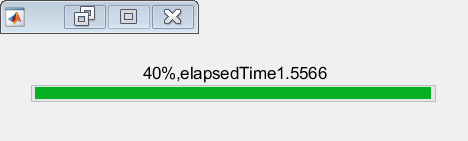

APNum=10;
BS_RFNum=4;
AP_RFNum_In=2;
AP_RFNum_Out=4;
FrameNum=6;
for UserNum=50:10:50
SimNum=40;
Record=table(zeros(SimNum,1),zeros(SimNum,1),zeros(SimNum,1),zeros(SimNum,1),...
    'VariableNames',{'LP','QP','HP','LB'});
LP=zeros(SimNum,FrameNum);
QP=zeros(SimNum,FrameNum);
LB=zeros(SimNum,2*FrameNum);
fbar = waitbar(0,'Please wait...');
for Sim=1:SimNum
tic;
Res=400;
close all;
%生成AP坐标------------------------------------------
load("Network1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out)+"\"...
    +num2str(Sim)+".mat");

% % 绘图查看网络-----------------------------------------------------
% scatter(real(UserPosition),imag(UserPosition));
% hold on;
% scatter(real(APPosition),imag(APPosition),'filled');
% hold off;

%预选参数----------------------------------------------------------
User_LinkChoice=2;%用户筛选链路个数
User_threshold=6e-11;
AP_threshold=8e-10; %基站链路选择阈值
User_RFNum=1;
beta=0.7;% 每个frame链路速率更新速度
epsilon=1e-3; % 修正时使用的差错率

%仿真参数----------------------------------------------------------
P_Noise = 1e-9; %接收端白噪声
IF_threshold=0.08; %干涉阈值（link1和link2接收端串扰能量比例下限）
p0=0.3; %基站波束在发射端的串扰
p_self=0; %全双工抵消后发射对接收的干扰
APGain = 2; UserGain = 1; %AP天线的额外增益
APPmax = 1; BSPmax = 2.5; %发射能量
frequency = 60e9; c = 3e8; alpha = 0.0037; %电磁波参数假设

% X1:接收设备位置  X2:AP发送设备位置，计算发送设备到接收设备的功率---------
[r,Angle]=xy2ra([APPosition; UserPosition], APPosition.');
[g,k]=TGain(reshape(Angle,[],1),f,Nt,thetatop,thetabottom,p0);
GT = reshape(g*APGain,size(Angle)); %发射波束的增益
RF_Send = reshape(k,size(Angle)); %发射使用的波束
GR = [GT(1:APNum,:).';UserGain * ones(UserNum,APNum)]; %接收端的增益
RF_Receive = [RF_Send(1:APNum,:).';zeros(UserNum,APNum)]; %接收端的波束
PT = ones(size(GT)) .* APPmax; PT(:,1) = BSPmax; %发射功率
PR = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r); %接收到的功率
for i=1:APNum
    PR(i,i)=0;
end
PR=PR.';%node->node
RF_Send=RF_Send.';
RF_Receive=RF_Receive.';
ADJChart=PR;

%生成Link和Node-------------------------------------------------------------------------------------------
LinkNum=sum(ADJChart>0,"all");
NodeNum=size(ADJChart,2);
Node=table(complex(zeros(NodeNum,1)),cell(NodeNum,1),cell(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),...
    'VariableNames',{'Position','In','Out','DataDemand','RFNum_In','RFNum_Out'});
Link=table(zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    cell(LinkNum,1),cell(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    zeros(LinkNum,1),...
    'VariableNames',{'From','To','RF_Send','RF_Receive','Throughput','IF_nDuplex','IF_Duplex',...
    'PR','IFPower','Rate','Time','SendPower'});
head=0;tail=0;
Node.Position(1:APNum)=APPosition;
Node.Position(APNum+1:end)=UserPosition;
Node.RFNum_Out(1)=BS_RFNum;
Node.RFNum_In(2:APNum)=AP_RFNum_In;
Node.RFNum_Out(2:APNum)=AP_RFNum_Out;
Node.RFNum_In(APNum+1:end)=User_RFNum;
for i=1:size(ADJChart,1)
    temp=find(ADJChart(i,:)>0);
    head=tail+1;
    tail=head+length(temp)-1;
    Node.Out{i}=head:tail;
    for j=1:length(temp)
        Node.In{temp(j)}=[Node.In{temp(j)},head+j-1];
        Link.From(head+j-1)=i;
        Link.To(head+j-1)=temp(j);
        Link.RF_Send(head+j-1)=RF_Send(i,temp(j));
        Link.RF_Receive(head+j-1)=RF_Receive(i,temp(j));
        Link.PR(head+j-1)=PR(i,temp(j));
    end
end
Node.DataDemand(APNum+1:end)=Demand;
Link.SendPower=ones(LinkNum,1)*APPmax;
Link.SendPower(Node.Out{1})=BSPmax;

% 按功率筛选出BS，AP之间的链路----------------------------------
AP2AP=PR(1:APNum,1:APNum);
AP2AP=(AP2AP>AP_threshold & AP2AP<inf).*AP2AP;
Level=cell(4,1);Remain=1:APNum;
Level{1}=1;Remain=setdiff(Remain,Level{1});
i=1;
while(~isempty(Remain))
    AP2AP(Remain,Level{i})=0;
    Level{i+1}=Remain(sum(AP2AP(Level{i},Remain)>0,1)>0);
    Remain=setdiff(Remain,Level{i+1});
    i=i+1;
end
% AP2AP_Active=AP2AP.'>0;
RF_Send=RF_Send.*(ADJChart>0);

%获得两两之间干涉---------------------------------------------------------------------------
[r,theta]=xy2ra(Node.Position(Link.To),Node.Position(Link.From).');%[Link.To, Link.From]
GT=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Send.',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta))*APGain; %[Link.To, Link.From]
AP_Index=Link.To<=APNum;
[~,theta]=xy2ra(Node.Position(Link.From),Node.Position(Link.To(AP_Index)).');
GR=ones(size(GT))*UserGain;
GR(AP_Index,:)=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Receive(AP_Index).',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta)).'*APGain; %[Link.To, Link.From]
PT =  ones(size(GT)) .* APPmax; PT(:,Node.Out{1}) = BSPmax;
IFPower = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r);%[Link.To<-Link.From]
IFPower(r<1e-6)=p_self;%全双工的结果
Ratio = IFPower./diag(IFPower);
IF_Graph=Ratio>IF_threshold;
IF_Graph=IF_Graph | IF_Graph.';
IF_Graph=xor(IF_Graph,eye(LinkNum));

%RL学习--------------------------------------------------------------------------------------
%根据接收功率初始化PI，并求出结点的throughput.按照实际[To, From]的矩阵形式储存，不过在RL种正好反向
% PR,PI,Time,PIF=
% [    | BS AP]
% [BS  | -- --]
% [AP  | -- --]
% [User| -- --]
% RFIN, RFOUT:NodeNum*1
%假设两两边之间的干涉已经度量出来
%IFPower=[NodeNum*APNum, NodeNum*APNum] [Link<-Link],要求自己对自己是0.
ADJChart=ADJChart.';
Power=reshape(ADJChart(2:end,:),[],1);
RateStandard=1e10;
RFIN=[AP_RFNum_In*ones(APNum,1);User_RFNum*ones(UserNum,1)];
RFOUT=AP_RFNum_Out*ones(1,APNum);
IFPower=IFPower-IFPower.*eye(size(IFPower,1));
lambda0=0.03;lambda1=1;
gamma=0.3;%discount factor
xi=0.5;
eta=1.5;%概率差异
PIF=zeros(NodeNum,APNum);%初始化干涉能量
PI=ADJChart./sum(ADJChart,2);%初始化概率
PI(1:APNum,:)=PI(1:APNum,:).*AP2AP_Active;
PI(1:APNum,:)=PI(1:APNum,:)./sum(PI(1:APNum,:),2);
PI(1,:)=0;
V=zeros(NodeNum,1);
Gap_PI=inf;
lambda2=0.4;
while(Gap_PI>1e-3)
    PI_old=PI;
    
%     C=2*pi*frequency*log2(1+ADJChart./(PIF+P_Noise))/RateStandard;
%     q=zeros(NodeNum,1);
%     q(APNum+1:end)=Demand;
%     %学习结点的throughput q.
%     Gap_q=inf;
%     while(Gap_q>1e-2)
%         q_old=q;
%         q(1:APNum)=(q.'*PI).';
%         Gap_q=max(abs(q_old-q));
%     end
% %     linkdata=q.*PI;
% %     temp=min(linkdata(1:APNum,:),linkdata(1:APNum,:).');
% %     linkdata(1:APNum,:)=linkdata(1:APNum,:)-temp;
% %     PI=linkdata./sum(linkdata,2);
% %     PI(1,:)=0;
%     Time=q.*PI./C;
%     Time(isnan(Time) | Time==inf)=0;
%     Tmax_in=max([sum(Time,2)./RFIN,Time],[],2);
%     Tmax_out=max([sum(Time,1)./RFOUT(1:APNum).';Time],[],1);
%     Tmax=max(max(Tmax_in),max(Tmax_out));
%     Time_l=reshape(Time(2:end,:),[],1);

    %学习C
    Gap_C=inf;
    C=zeros(size(PI));
    while(Gap_C>1e-1)
        C_old=C;
        C=2*pi*frequency*log2(1+ADJChart./(PIF+P_Noise))/RateStandard;%初始化速率
        Gap_C=max(abs(C-C_old),[],'all');
        q=zeros(NodeNum,1);
        q(APNum+1:end)=Demand;
        %学习结点的throughput q.
        Gap_q=inf;
        while(Gap_q>1e-2)
            q_old=q;
            q(1:APNum)=(q.'*PI).';
            Gap_q=max(abs(q_old-q));
        end
        Time=q.*PI./C;
        Time(isnan(Time) | Time==inf)=0;
        Tmax_in=max([sum(Time,2)./RFIN,Time],[],2);
        Tmax_out=max([sum(Time,1)./RFOUT(1:APNum).';Time],[],1);
        Tmax=max(max(Tmax_in),max(Tmax_out));
        Time_l=reshape(Time(2:end,:),[],1);
%         PIF_l=(IFPower.*(~IF_Graph))*Time_l/Tmax;
        PIF_l=IFPower*Time_l/Tmax;
        PIF(2:end,:)=reshape(PIF_l,NodeNum-1,[]);
    end
    R=q./C/Tmax.*(...
        lambda0*(PIF+P_Noise)./ADJChart+...
        lambda0*[zeros(1,APNum);reshape((IFPower.'*Time_l)./Power,NodeNum-1,[])]+...
        lambda1*Tmax_in./RFIN+...
        lambda1*Tmax_out./RFOUT);
    R(R==inf | isnan(R))=100;
    Gap_V=inf;
    while(Gap_V>1e-3)
        V_old=V;
        V=sum(PI.*R,2)+gamma*PI*V(1:APNum);
        Gap_V=max(abs(V-V_old));
    end
    Q=R+gamma*V(1:APNum).';
    Q_inv=(1./Q).^eta;
    Q_inv(eye(size(Q_inv))>0)=0;
    PI=Q_inv./sum(Q_inv,2);
    PI=xi*PI+(1-xi)*PI_old;
    PI(1,:)=0;
    Gap_PI=max(abs(PI_old-PI),[],'all');
end

ADJChart=ADJChart.';%转成node->node
C=C'*RateStandard;
% ADJChart(:,1:APNum)=AP2AP;
ADJChart(:,1:APNum)=(PI(1:APNum,:)>1/1.5/APNum).'.*PR(:,1:APNum)
ADJChart(:,APNum+1:end)=0;
%按PI筛选出AP与User之间的链路----------------------------------
AP2User=PR(:,APNum+1:end);%node->node
%按照概率前k个进行选择
[~,I]=maxk(PI(APNum+1:end,:),User_LinkChoice,2);
for i=1:UserNum
    ADJChart(I(i,:),i+APNum)=AP2User(I(i,:),i);
end
RF_Send=RF_Send.*(ADJChart>0);

%生成Link和Node-------------------------------------------------------------------------------------------
LinkNum=sum(ADJChart>0,"all");
NodeNum=size(ADJChart,2);
Node=table(complex(zeros(NodeNum,1)),cell(NodeNum,1),cell(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),...
    'VariableNames',{'Position','In','Out','DataDemand','RFNum_In','RFNum_Out'});
Link=table(zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    cell(LinkNum,1),cell(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    zeros(LinkNum,1),...
    'VariableNames',{'From','To','RF_Send','RF_Receive','Throughput','IF_nDuplex','IF_Duplex',...
    'PR','IFPower','Rate','Time','SendPower'});
head=0;tail=0;
Node.Position(1:APNum)=APPosition;
Node.Position(APNum+1:end)=UserPosition;
Node.RFNum_Out(1)=BS_RFNum;
Node.RFNum_In(2:APNum)=AP_RFNum_In;
Node.RFNum_Out(2:APNum)=AP_RFNum_Out;
Node.RFNum_In(APNum+1:end)=User_RFNum;
for i=1:size(ADJChart,1)
    temp=find(ADJChart(i,:)>0);
    head=tail+1;
    tail=head+length(temp)-1;
    Node.Out{i}=head:tail;
    for j=1:length(temp)
        Node.In{temp(j)}=[Node.In{temp(j)},head+j-1];
        Link.From(head+j-1)=i;
        Link.To(head+j-1)=temp(j);
        Link.RF_Send(head+j-1)=RF_Send(i,temp(j));
        Link.RF_Receive(head+j-1)=RF_Receive(i,temp(j));
        Link.PR(head+j-1)=PR(i,temp(j));
        Link.Rate(head+j-1)=C(i,temp(j));
    end
end
Node.DataDemand(APNum+1:end)=Demand;
Link.SendPower=ones(LinkNum,1)*APPmax;
Link.SendPower(Node.Out{1})=BSPmax;

%绘制干涉图------------------------------------------------------------------------------
[r,theta]=xy2ra(Node.Position(Link.To),Node.Position(Link.From).');%[Link.To, Link.From]
GT=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Send.',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta))*APGain; %[Link.To, Link.From]
AP_Index=Link.To<=APNum;
[~,theta]=xy2ra(Node.Position(Link.From),Node.Position(Link.To(AP_Index)).');
GR=ones(size(GT))*UserGain;
GR(AP_Index,:)=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Receive(AP_Index).',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta)).'*APGain; %[Link.To, Link.From]
PT =  ones(size(GT)) .* APPmax; PT(:,Node.Out{1}) = BSPmax;
PR = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r);%[Link.To<-Link.From]
PR(r<1e-6)=p_self;%全双工的结果
Ratio = PR./diag(PR);
IF_Graph=Ratio>IF_threshold;
IF_Graph=IF_Graph | IF_Graph.';
IF_Graph=xor(IF_Graph,eye(LinkNum));
for i=1:LinkNum
    Link.IF_nDuplex{i}=find(IF_Graph(i,:));
end

RateStandard=median(Link.Rate);
Link.Rate=Link.Rate./RateStandard;

%完全图------------------------------------------------------------
Cliq=false(5000,LinkNum);Cliqend=0;
BronKerbosch(false(1,LinkNum),true(1,LinkNum),false(1,LinkNum));
Cliq=Cliq(1:Cliqend,:);

%LP求解---------------------------------------------------------
A=zeros(2*APNum+LinkNum+size(Cliq,1)-1,LinkNum+1);
b=zeros(size(A,1),1);
Aeq=zeros(NodeNum-1,LinkNum+1);
beq=zeros(size(Aeq,1),1);
%流量守恒
head=0;
for k=1:APNum-1
    In=Node.In{k+1};Out=Node.Out{k+1};
    Aeq(head+k,In)=-Link.Rate(In);
    Aeq(head+k,Out)=Link.Rate(Out);
    beq(head+k)=0;
end
%需求满足
head=head+k;
for k=1:UserNum
    In=Node.In{k+APNum};
    Aeq(k+head,In)=Link.Rate(In);
    beq(k+head)=Node.DataDemand(k+APNum);
end
%接收链路数限制
head=0;
for k=1:APNum-1
    In=Node.In{k+1};
    A(head+k,In)=1./Node.RFNum_In(k+1);
    A(head+k,end)=-1;
    b(head+k)=0;
end
%发送链路数限制
head=head+k;
for k=1:APNum
    Out=Node.Out{k};
    A(head+k,Out)=1./Node.RFNum_Out(k);
    A(head+k,end)=-1;
    b(head+k)=0;
end
%完全图约束    
head=head+k;
A(head+1:head+size(Cliq,1),1:size(Cliq,2))=Cliq;
A(head+1:head+size(Cliq,1),end)=-1;
lb=zeros(LinkNum+1,1);
a=ones(LinkNum+1,1)*1e-4;
a(end)=1;
x = linprog(a,A,b,Aeq,beq,lb,[],option_linprog);

%Frame1调度-------------------------------------------------------
AP=table([Node.RFNum_In(1:APNum);Node.RFNum_Out(1:APNum)],cell(APNum*2,1),...
    'VariableNames',{'RFNum','InOut'});
for i=1:APNum
    AP.InOut{i}=[Node.In{i}];
end
for i=1:APNum
    AP.InOut{i+APNum}=[Node.Out{i}];
end
Link.Throughput=x(1:end-1).*Link.Rate;
Link.Time=x(1:end-1);
TimeStandard=x(end)/Res;
Link.Time(Link.Time<1e-6)=0;
Link.Time=ceil(Link.Time/TimeStandard);
IFLink = table((1:LinkNum).', Link.IF_nDuplex, Link.Time, zeros(LinkNum,1), false(LinkNum,1),...
    cell(LinkNum,1),'VariableNames', {'Node','Adjacency','Demand','Degree','Found','Source'});
for i = 1:LinkNum
    IFLink.Degree(i) = sum(IFLink.Demand(IFLink.Adjacency{i})) + IFLink.Demand(i);
    if(Link.To(i)<=APNum)
        IFLink.Source{i}=[Link.From(i)+APNum,Link.To(i)];
    else
        IFLink.Source{i}=Link.From(i)+APNum;
    end
end
[Scheme,TimeLength,TotalSlotNum,Availability,RFUsage]...
=Schedule(IFLink,2*Res,AP,[],[],[]);
[Scheme,RFUsage,TimeLength]=SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
[Scheme,Rate,TimeLength,Availability,RFUsage,EngyRecv,AcData]...
    =DemandMeet(Scheme,Availability,RFUsage,PR,IFLink,Link,AP,epsilon,TimeLength,frequency,P_Noise,RateStandard,TimeStandard);
TimeNeeded=TimeLength*TimeStandard/RateStandard;

%使用两种方法求解-------------------------------------------------------------
LP(Sim,1)=TimeNeeded;
QP(Sim,1)=TimeNeeded;
LB(Sim,[1,FrameNum+1])=x(end)/RateStandard;
InitRate=Link.Rate;
InitScheme=Scheme;
Initx=x;
InitTimeLength=TimeLength;
InitTimeStandard=TimeStandard;
InitTime=IFLink.Demand;
% %使用LP方法求解--------------------------------------------------------------
% for frame=1:FrameNum-1
%     %重新计算干涉、链路的速率--------------------------------------------------
%     EngyRecv=PR*Scheme;
%     Rate=2*pi*frequency*log2(1+Link.PR./(EngyRecv+P_Noise-Link.PR.*Scheme));
%     AveRate=sum(Rate.*Scheme,2)./IFLink.Demand;
%     NaNIndex=isnan(AveRate);
%     AveRate(NaNIndex)=mean(Rate(NaNIndex,:),2);
%     AveRate=AveRate/RateStandard;
%     Link.Rate=Link.Rate+beta*(AveRate-Link.Rate);
%     %更新Aeq-----------------------------------------------------------------
%     %流量守恒
%     head=0;
%     for k=1:APNum-1
%         In=Node.In{k+1};Out=Node.Out{k+1};
%         Aeq(head+k,In)=-Link.Rate(In);
%         Aeq(head+k,Out)=Link.Rate(Out);
%         beq(head+k)=0;
%     end
%     %需求满足
%     head=head+k;
%     for k=1:UserNum
%         In=Node.In{k+APNum};
%         Aeq(k+head,In)=Link.Rate(In);
%         beq(k+head)=Node.DataDemand(k+APNum);
%     end
%     %LP问题求解--------------------------------------------------------------
%     x = linprog(a,A,b,Aeq,beq,lb,[],option_linprog);
%     %调度-------------------------------------------------------------------
%     Link.Throughput=x(1:end-1).*Link.Rate;
%     Link.Time=x(1:end-1);
%     TimeStandard=x(end)/Res;
%     Link.Time(Link.Time<1e-6)=0;
%     Link.Time=ceil(Link.Time/TimeStandard);
%     IFLink.Demand=Link.Time;
%     [Scheme,TimeLength,TotalSlotNum,Availability,RFUsage]...
%     =Schedule(IFLink,2*Res,AP,[],[],[]);
%     [Scheme,RFUsage,TimeLength]=SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
%     [Scheme,Rate,TimeLength,Availability,RFUsage,EngyRecv,AcData]...
%         =DemandMeet(Scheme,Availability,RFUsage,PR,IFLink,Link,AP,epsilon,TimeLength,frequency,P_Noise,RateStandard,TimeStandard);
%     TimeNeeded=TimeLength*TimeStandard/RateStandard;
%     LP(Sim,frame+1)=TimeNeeded;
%     LB(Sim,frame+1)=x(end)/RateStandard;
% end
    
if(TimeLength>=Res)
    %使用QP求解----------------------------------------------------------------
    Link.Rate=InitRate;
    Scheme=InitScheme;
    x=Initx;
    TimeLength=InitTimeLength;
    TimeStandard=InitTimeStandard;
    IFLink.Demand=InitTime;
    
    %准备好初始参数-------------------------------------------------------------
    Q=double(IF_Graph);Q(end+1,end+1)=0;
    e=eig(Q);
    e=min(e)-1;
    Q_m=eye(size(Q,1))*e;
    Q_p=Q-Q_m;
    for frame=1:FrameNum-1
        %重新计算干涉、链路的速率--------------------------------------------------
        EngyRecv=PR*Scheme;
        Rate=2*pi*frequency*log2(1+Link.PR./(EngyRecv+P_Noise-Link.PR.*Scheme));
        AveRate=sum(Rate.*Scheme,2)./IFLink.Demand;
        NaNIndex=or(isnan(AveRate),AveRate==inf);
        AveRate(NaNIndex)=mean(Rate(NaNIndex,:),2);
        AveRate=AveRate/RateStandard;
        Link.Rate=Link.Rate+beta*(AveRate-Link.Rate);
        %更新Aeq-----------------------------------------------------------------
        %流量守恒
        head=0;
        for k=1:APNum-1
            In=Node.In{k+1};Out=Node.Out{k+1};
            Aeq(head+k,In)=-Link.Rate(In);
            Aeq(head+k,Out)=Link.Rate(Out);
            beq(head+k)=0;
        end
        %需求满足
        head=head+k;
        for k=1:UserNum
            In=Node.In{k+APNum};
            Aeq(k+head,In)=Link.Rate(In);
            beq(k+head)=Node.DataDemand(k+APNum);
        end
        %QP问题求解--------------------------------------------------------------
        x_old=x;
        E_IFTime=(TimeLength-Res)*TimeStandard;
        T=(TimeLength*TimeStandard);
        alpha=E_IFTime*4*T/(x_old.'*Q*x_old);
        Error=inf;
        s=0;
        if(TimeLength > Res * 1.01)
            while(Error>1e-3 && s<2)
                x=quadprog(Q_p/abs(e),(x_old.'*Q_m+2*T*a.'/alpha)/abs(e),A,b,Aeq,beq,lb,[],[],option_quadprog);
                Error=max(abs(x-x_old));
                x_old=x;
                s=s+1;
            end
        else
            x = linprog(a,A,b,Aeq,beq,lb,[],option_linprog);
        end
        %调度-------------------------------------------------------------------
        Link.Throughput=x(1:end-1).*Link.Rate;
        Link.Time=x(1:end-1);
        TimeStandard=x(end)/Res;
        Link.Time(Link.Time<1e-6)=0;
        Link.Time=ceil(Link.Time/TimeStandard);
        IFLink.Demand=Link.Time;
        [Scheme,TimeLength,TotalSlotNum,Availability,RFUsage]...
        =Schedule(IFLink,2*Res,AP,[],[],[]);
        [Scheme,RFUsage,TimeLength]=SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
        [Scheme,Rate,TimeLength,Availability,RFUsage,EngyRecv,AcData]...
            =DemandMeet(Scheme,Availability,RFUsage,PR,IFLink,Link,AP,epsilon,TimeLength,frequency,P_Noise,RateStandard,TimeStandard);
        TimeNeeded=TimeLength*TimeStandard/RateStandard;
        QP(Sim,frame+1)=TimeNeeded;
        LB(Sim,FrameNum+frame+1)=x(end)/RateStandard;
    end
else
    QP(Sim,:)=LP(Sim,:);
    LB(Sim,FrameNum+1:end)=LB(Sim,1:FrameNum);
end

% %启发方法---------------------------------------------------------------------------
% K=2;
% Node.Distribute=cell(NodeNum,1);
% Node.RouteFrom=cell(NodeNum,1);
% Link.Throughput=zeros(LinkNum,1);
% Link.Time=zeros(LinkNum,1);
% for i=APNum+1:NodeNum
%     [~,I]=maxk(Link.Rate(Node.In{i}),K);
%     Node.RouteFrom{i}=Node.In{i}(I);
%     [R,I]=max(Link.Rate(Node.RouteFrom{i}));
%     Node.Distribute{i}=zeros(1,length(Node.RouteFrom{i}));
%     Node.Distribute{i}(I)=1;
% end
% LE=length(Level);
% while(isempty(Level{LE}))
%     LE=LE-1;
% end
% for i=LE:-1:2
%     for j=1:length(Level{i})
%         APn=Level{i}(j);
%         Candidate=Node.In{APn};
%         Candidate=Candidate(ismember(Link.From(Candidate),Level{i-1}));
%         [~,I]=maxk(Candidate,K);
%         Node.RouteFrom{APn}=Candidate(I);
%         [R,I]=max(Link.Rate(Node.RouteFrom{APn}));
%         Node.Distribute{APn}=zeros(1,length(Node.RouteFrom{APn}));
%         Node.Distribute{APn}(I)=1;
%     end
% end
% TimeAssign(APNum,NodeNum,Level,LE);
% IFLink.Demand=Link.Time;
% [Scheme,TimeLength,TotalSlotNum,...
%     Availability,RFUsage]=Schedule(IFLink,Res*4,AP,[],[],[]);
% [Scheme,RFUsage,TimeLength,Availability]...
%     =SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
% flag=true;
% while(flag)
%     flag=false;
%     for i=NodeNum:-1:APNum+1
%         flag=flag|Redistribute(i);
%     end
%     for i=LE-1:2
%         for j=1:length(Level{i})
%             flag=flag|Redistribute(j);
%         end
%     end
% end
% [Scheme,RFUsage,TimeLength,Availability]...
%     =SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
% TimeNeeded=TimeLength*TimeStandard/RateStandard;


%对比-----------------------------------------------------------
Record.LP(Sim)=mean(LP(Sim,:));
Record.QP(Sim)=mean(QP(Sim,:));
% Record.HP(Sim)=TimeNeeded;
Record.LB(Sim)=mean(LB(Sim,:));
elapsedTime=toc;
waitbar(Sim/SimNum,fbar,num2str(Sim)+"%,elapsedTime"+num2str(elapsedTime));
end
% save("Result1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out)+"_"...
%     +num2str(Sim)+"_RL.mat","Record","LP","QP","LB");
end

HP

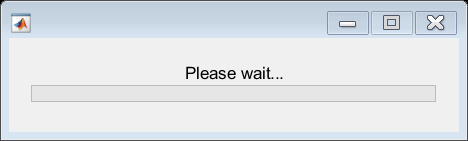

APNum=10;
BS_RFNum=4;
AP_RFNum_In=2;
AP_RFNum_Out=4;
FrameNum=8;
for UserNum=50:10:120
SimNum=40;
Record=table(zeros(SimNum,1),zeros(SimNum,1),...
    'VariableNames',{'LR','HP'});
LP=zeros(SimNum,FrameNum);
QP=zeros(SimNum,FrameNum);
LB=zeros(SimNum,2*FrameNum);
fbar = waitbar(0,'Please wait...');
for Sim=1:SimNum
tic;
Res=400;
close all;
%生成AP坐标------------------------------------------
load("Network1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out)+"\"...
    +num2str(Sim)+".mat");

% % 绘图查看网络-----------------------------------------------------
% scatter(real(UserPosition),imag(UserPosition));
% hold on;
% scatter(real(APPosition),imag(APPosition),'filled');
% hold off;

%预选参数----------------------------------------------------------
User_LinkChoice=2;%用户筛选链路个数
User_threshold=6e-11;
AP_threshold=8e-10; %基站链路选择阈值
BS_RFNum=4;
AP_RFNum_In=2;
AP_RFNum_Out=4;
User_RFNum=1;
beta=0.7;% 每个frame链路速率更新速度
epsilon=1e-3; % 修正时使用的差错率

%仿真参数----------------------------------------------------------
P_Noise = 1e-9; %接收端白噪声
IF_threshold=0.08; %干涉阈值（link1和link2接收端串扰能量比例下限）
p0=0.3; %基站波束在发射端的串扰
p_self=0; %全双工抵消后发射对接收的干扰
APGain = 2; UserGain = 1; %AP天线的额外增益
APPmax = 1; BSPmax = 2.5; %发射能量
frequency = 60e9; c = 3e8; alpha = 0.0037; %电磁波参数假设

% X1:接收设备位置  X2:AP发送设备位置，计算发送设备到接收设备的功率---------
[r,Angle]=xy2ra([APPosition; UserPosition], APPosition.');
[g,k]=TGain(reshape(Angle,[],1),f,Nt,thetatop,thetabottom,p0);
GT = reshape(g*APGain,size(Angle)); %发射波束的增益
RF_Send = reshape(k,size(Angle)); %发射使用的波束
GR = [GT(1:APNum,:).';UserGain * ones(UserNum,APNum)]; %接收端的增益
RF_Receive = [RF_Send(1:APNum,:).';zeros(UserNum,APNum)]; %接收端的波束
PT = ones(size(GT)) .* APPmax; PT(:,1) = BSPmax; %发射功率
PR = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r); %接收到的功率
for i=1:APNum
    PR(i,i)=0;
end
PR=PR.';
RF_Send=RF_Send.';
RF_Receive=RF_Receive.';
ADJChart=PR;

%生成Link和Node-------------------------------------------------------------------------------------------
LinkNum=sum(ADJChart>0,"all");
NodeNum=size(ADJChart,2);
Node=table(complex(zeros(NodeNum,1)),cell(NodeNum,1),cell(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),...
    'VariableNames',{'Position','In','Out','DataDemand','RFNum_In','RFNum_Out'});
Link=table(zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    cell(LinkNum,1),cell(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    zeros(LinkNum,1),...
    'VariableNames',{'From','To','RF_Send','RF_Receive','Throughput','IF_nDuplex','IF_Duplex',...
    'PR','IFPower','Rate','Time','SendPower'});
head=0;tail=0;
Node.Position(1:APNum)=APPosition;
Node.Position(APNum+1:end)=UserPosition;
Node.RFNum_Out(1)=BS_RFNum;
Node.RFNum_In(2:APNum)=AP_RFNum_In;
Node.RFNum_Out(2:APNum)=AP_RFNum_Out;
Node.RFNum_In(APNum+1:end)=User_RFNum;
for i=1:size(ADJChart,1)
    temp=find(ADJChart(i,:)>0);
    head=tail+1;
    tail=head+length(temp)-1;
    Node.Out{i}=head:tail;
    for j=1:length(temp)
        Node.In{temp(j)}=[Node.In{temp(j)},head+j-1];
        Link.From(head+j-1)=i;
        Link.To(head+j-1)=temp(j);
        Link.RF_Send(head+j-1)=RF_Send(i,temp(j));
        Link.RF_Receive(head+j-1)=RF_Receive(i,temp(j));
        Link.PR(head+j-1)=PR(i,temp(j));
    end
end
Node.DataDemand(APNum+1:end)=Demand;
Link.SendPower=ones(LinkNum,1)*APPmax;
Link.SendPower(Node.Out{1})=BSPmax;

% 按功率筛选出BS，AP之间的链路----------------------------------
AP2AP=PR(1:APNum,1:APNum);
AP2AP=(AP2AP>AP_threshold & AP2AP<inf).*AP2AP;
Level=cell(4,1);Remain=1:APNum;
Level{1}=1;Remain=setdiff(Remain,Level{1});
i=1;
while(~isempty(Remain))
    AP2AP(Remain,Level{i})=0;
    Level{i+1}=Remain(sum(AP2AP(Level{i},Remain)>0,1)>0);
    Remain=setdiff(Remain,Level{i+1});
    i=i+1;
end
AP2AP_Active=AP2AP.'>0;
RF_Send=RF_Send.*(ADJChart>0);

%获得两两之间干涉---------------------------------------------------------------------------
[r,theta]=xy2ra(Node.Position(Link.To),Node.Position(Link.From).');%[Link.To, Link.From]
GT=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Send.',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta))*APGain; %[Link.To, Link.From]
AP_Index=Link.To<=APNum;
[~,theta]=xy2ra(Node.Position(Link.From),Node.Position(Link.To(AP_Index)).');
GR=ones(size(GT))*UserGain;
GR(AP_Index,:)=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Receive(AP_Index).',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta)).'*APGain; %[Link.To, Link.From]
PT =  ones(size(GT)) .* APPmax; PT(:,Node.Out{1}) = BSPmax;
IFPower = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r);%[Link.To<-Link.From]
IFPower(r<1e-6)=p_self;%全双工的结果


%RL学习--------------------------------------------------------------------------------------
%根据接收功率初始化PI，并求出结点的throughput.按照实际[To, From]的矩阵形式储存，不过在RL种正好反向
% PR,PI,Time,PIF=
% [    | BS AP]
% [BS  | -- --]
% [AP  | -- --]
% [User| -- --]
% RFIN, RFOUT:NodeNum*1
%假设两两边之间的干涉已经度量出来
%IFPower=[NodeNum*APNum, NodeNum*APNum] [Link<-Link],要求自己对自己是0.
ADJChart=ADJChart.';
Power=reshape(ADJChart(2:end,:),[],1);
RateStandard=1e10;
RFIN=[AP_RFNum_In*ones(APNum,1);User_RFNum*ones(UserNum,1)];
RFOUT=AP_RFNum_Out*ones(1,APNum);
IFPower=IFPower-IFPower.*eye(size(IFPower,1));
lambda0=0.01;lambda1=1;
gamma=0.3;%discount factor
xi=0.5;
eta=1.5;%概率差异
PIF=zeros(NodeNum,APNum);%初始化干涉能量
PI=ADJChart./sum(ADJChart,2);%初始化概率
PI(1:APNum,:)=PI(1:APNum,:).*AP2AP_Active;
PI(1:APNum,:)=PI(1:APNum,:)./sum(PI(1:APNum,:),2);
PI(1,:)=0;
V=zeros(NodeNum,1);
Gap_PI=inf;
while(Gap_PI>1e-3)
    PI_old=PI;
    
    C=2*pi*frequency*log2(1+PR_dir./(PIF+P_Noise));%初始化速率
    q=zeros(NodeNum,1);
    q(APNum+1:end)=Demand;
    %学习结点的throughput q.
    Gap_q=inf;
    while(Gap_q>1e-2)
        q_old=q;
        q(1:APNum)=(q.'*PI).';
        Gap_q=max(abs(q_old-q));
    end
%     linkdata=q.*PI;
%     temp=min(linkdata(1:APNum,:),linkdata(1:APNum,:).');
%     linkdata(1:APNum,:)=linkdata(1:APNum,:)-temp;
%     PI=linkdata./sum(linkdata,2);
%     PI(1,:)=0;
    Time=q.*PI./C;
    Time(isnan(Time) | Time==inf)=0;
    Tmax_in=max([sum(Time,2)./RFIN,Time],[],2);
    Tmax_out=max([sum(Time,1)./RFOUT(1:APNum).';Time],[],1);
    Tmax=max(max(Tmax_in),max(Tmax_out));
    Time_l=reshape(Time(2:end,:),[],1);

%     %学习C
%     Gap_C=inf;
%     C=zeros(size(PI));
%     while(Gap_C>1e-1)
%         C_old=C;
%         C=2*pi*frequency*log2(1+ADJChart./(PIF+P_Noise))/RateStandard;%初始化速率
%         Gap_C=max(abs(C-C_old),[],'all');
%         q=zeros(NodeNum,1);
%         q(APNum+1:end)=Demand;
%         %学习结点的throughput q.
%         Gap_q=inf;
%         while(Gap_q>1e-2)
%             q_old=q;
%             q(1:APNum)=(q.'*PI).';
%             Gap_q=max(abs(q_old-q));
%         end
%         Time=q.*PI./C;
%         Time(isnan(Time) | Time==inf)=0;
%         Tmax_in=max([sum(Time,2)./RFIN,Time],[],2);
%         Tmax_out=max([sum(Time,1)./RFOUT(1:APNum).';Time],[],1);
%         Tmax=max(max(Tmax_in),max(Tmax_out));
%         Time_l=reshape(Time(2:end,:),[],1);
%         PIF_l=IFPower*Time_l/Tmax;
%         PIF(2:end,:)=reshape(PIF_l,NodeNum-1,[]);
%     end
    R=q./C/Tmax.*(...
        lambda0*[zeros(1,APNum);reshape((IFPower.'*Time_l+P_Noise)./Power,NodeNum-1,[])]+...
        lambda1*Tmax_in./RFIN+...
        lambda1*Tmax_out./RFOUT);
    R(R==inf | isnan(R))=100;
    Gap_V=inf;
    while(Gap_V>1e-3)
        V_old=V;
        V=sum(PI.*R,2)+gamma*PI*V(1:APNum);
        Gap_V=max(abs(V-V_old));
    end
    Q=R+gamma*V(1:APNum).';
    Q_inv=(1./Q).^eta;
    Q_inv(eye(size(Q_inv))>0)=0;
    PI=Q_inv./sum(Q_inv,2);
    PI(1:APNum,:)=PI(1:APNum,:).*AP2AP_Active;
    PI(1:APNum,:)=PI(1:APNum,:)./sum(PI(1:APNum,:),2);
    PI=xi*PI+(1-xi)*PI_old;
    PI(1,:)=0;
    Gap_PI=max(abs(PI_old-PI),[],'all');
end

ADJChart=ADJChart.';
ADJChart(:,1:APNum)=AP2AP;
ADJChart(:,APNum+1:end)=0;
%按PI筛选出AP与User之间的链路----------------------------------
AP2User=PR(:,APNum+1:end);
%按照概率前k个进行选择
[~,I]=maxk(PI(APNum+1:end,:),User_LinkChoice,2);
for i=1:UserNum
    ADJChart(I(i,:),i+APNum)=AP2User(I(i,:),i);
end
RF_Send=RF_Send.*(ADJChart>0);

%生成Link和Node-------------------------------------------------------------------------------------------
LinkNum=sum(ADJChart>0,"all");
NodeNum=size(ADJChart,2);
Node=table(complex(zeros(NodeNum,1)),cell(NodeNum,1),cell(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),zeros(NodeNum,1),...
    'VariableNames',{'Position','In','Out','DataDemand','RFNum_In','RFNum_Out'});
Link=table(zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    cell(LinkNum,1),cell(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),zeros(LinkNum,1),...
    zeros(LinkNum,1),...
    'VariableNames',{'From','To','RF_Send','RF_Receive','Throughput','IF_nDuplex','IF_Duplex',...
    'PR','IFPower','Rate','Time','SendPower'});
head=0;tail=0;
Node.Position(1:APNum)=APPosition;
Node.Position(APNum+1:end)=UserPosition;
Node.RFNum_Out(1)=BS_RFNum;
Node.RFNum_In(2:APNum)=AP_RFNum_In;
Node.RFNum_Out(2:APNum)=AP_RFNum_Out;
Node.RFNum_In(APNum+1:end)=User_RFNum;
for i=1:size(ADJChart,1)
    temp=find(ADJChart(i,:)>0);
    head=tail+1;
    tail=head+length(temp)-1;
    Node.Out{i}=head:tail;
    for j=1:length(temp)
        Node.In{temp(j)}=[Node.In{temp(j)},head+j-1];
        Link.From(head+j-1)=i;
        Link.To(head+j-1)=temp(j);
        Link.RF_Send(head+j-1)=RF_Send(i,temp(j));
        Link.RF_Receive(head+j-1)=RF_Receive(i,temp(j));
        Link.PR(head+j-1)=PR(i,temp(j));
    end
end
Node.DataDemand(APNum+1:end)=Demand;
Link.SendPower=ones(LinkNum,1)*APPmax;
Link.SendPower(Node.Out{1})=BSPmax;

%标记出双向通信的AP对---------------------------------------------------------------------------
TwoWayLink=zeros(2*length(Level),2);
head=0;
for i=1:length(Level)
    ThisLevel=Level{i};
    for j=1:length(ThisLevel)
        for k=j+1:length(ThisLevel)
            temp=find(Link.From==ThisLevel(j) & Link.To==ThisLevel(k));
            if(~isempty(temp))
                TwoWayLink(head+1,1)=temp;
                TwoWayLink(head+1,2)=find(Link.From==ThisLevel(k) & Link.To==ThisLevel(j));
                head=head+1;
            end
        end
    end
end
TwoWayLink=TwoWayLink(1:head,:);

%绘制干涉图------------------------------------------------------------------------------
[r,theta]=xy2ra(Node.Position(Link.To),Node.Position(Link.From).');%[Link.To, Link.From]
GT=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Send.',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta))*APGain; %[Link.To, Link.From]
AP_Index=Link.To<=APNum;
[~,theta]=xy2ra(Node.Position(Link.From),Node.Position(Link.To(AP_Index)).');
GR=ones(size(GT))*UserGain;
GR(AP_Index,:)=reshape(...
    TGainCal(reshape(theta,[],1),...
    reshape(ones(size(theta)).*Link.RF_Receive(AP_Index).',[],1),...
    f,Nt,thetatop,thetabottom,p0)...
    ,size(theta)).'*APGain; %[Link.To, Link.From]
PT =  ones(size(GT)) .* APPmax; PT(:,Node.Out{1}) = BSPmax;
PR = PT.*GT.*GR.*(c./(4*pi*frequency*r)).^2.*exp(-alpha*r);%[Link.To<-Link.From]
PR(r<1e-6)=p_self;%全双工的结果
Ratio = PR./diag(PR);
IF_Graph=Ratio>IF_threshold;
IF_Graph=IF_Graph | IF_Graph.';
IF_Graph=xor(IF_Graph,eye(LinkNum));
for i=1:LinkNum
    Link.IF_nDuplex{i}=find(IF_Graph(i,:));
end

%初始化SINR及速率-----------------------------------------------
RFNum_Ave=sum(Node.RFNum_Out(1:APNum));
for i=1:LinkNum
    temp=PR(i,:);
    Link.IFPower(i)=(RFNum_Ave-1)*mean(temp(setdiff(1:LinkNum,[Link.IF_Duplex{i},Link.IF_nDuplex{i},i])));
end
Link.Rate=2*pi*frequency*log2(1+Link.PR./(Link.IFPower+P_Noise));
RateStandard=median(Link.Rate);
Link.Rate=Link.Rate./RateStandard;
%AP---------------------------------------------------------
AP=table([Node.RFNum_In(1:APNum);Node.RFNum_Out(1:APNum)],cell(APNum*2,1),...
    'VariableNames',{'RFNum','InOut'});
for i=1:APNum
    AP.InOut{i}=[Node.In{i}];
end
for i=1:APNum
    AP.InOut{i+APNum}=[Node.Out{i}];
end
%IFLink-----------------------------------------------------
IFLink = table((1:LinkNum).', Link.IF_nDuplex, Link.Time, zeros(LinkNum,1), false(LinkNum,1),...
    cell(LinkNum,1),'VariableNames', {'Node','Adjacency','Demand','Degree','Found','Source'});
for i = 1:LinkNum
%     IFLink.Degree(i) = sum(IFLink.Demand(IFLink.Adjacency{i})) + IFLink.Demand(i);
    if(Link.To(i)<=APNum)
        IFLink.Source{i}=[Link.From(i)+APNum,Link.To(i)];
    else
        IFLink.Source{i}=Link.From(i)+APNum;
    end
end
%启发方法---------------------------------------------------------------------------
K=2;
Node.Distribute=cell(NodeNum,1);
Node.RouteFrom=cell(NodeNum,1);
Link.Throughput=zeros(LinkNum,1);
Link.Time=zeros(LinkNum,1);
for i=APNum+1:NodeNum
%     [~,I]=maxk(Link.Rate(Node.In{i}),K);
    Node.RouteFrom{i}=Node.In{i};
%     [R,I]=max(Link.Rate(Node.RouteFrom{i}));
    I=Link.From(Node.RouteFrom{i});
    Node.Distribute{i}=PI(i,I)./sum(PI(i,I));
%     Node.Distribute{i}=1;
end
LE=length(Level);
while(isempty(Level{LE}))
    LE=LE-1;
end
for i=LE:-1:2
    for j=1:length(Level{i})
        APn=Level{i}(j);
        Candidate=Node.In{APn};
        Candidate=Candidate(ismember(Link.From(Candidate),Level{i-1}));
        [~,I]=maxk(Candidate,K);
        Node.RouteFrom{APn}=Candidate(I);
        [R,I]=max(Link.Rate(Node.RouteFrom{APn}));
        Node.Distribute{APn}=zeros(1,length(Node.RouteFrom{APn}));
        Node.Distribute{APn}(I)=1;
    end
end
TimeAssign(APNum,NodeNum,Level,LE);
IFLink.Demand=Link.Time;
[Scheme,TimeLength,TotalSlotNum,...
    Availability,RFUsage]=Schedule(IFLink,Res*4,AP,[],[],[]);
[Scheme,RFUsage,TimeLength,Availability]...
    =SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
Record.LR(Sim)=TimeLength/TimeStandard;
flag=true;
while(flag)
    flag=false;
    for i=NodeNum:-1:APNum+1
        flag=flag|Redistribute(i);
    end
    for i=LE-1:2
        for j=1:length(Level{i})
            flag=flag|Redistribute(j);
        end
    end
end
[Scheme,RFUsage,TimeLength,Availability]...
    =SchemeAdjust(Scheme,IFLink,AP,Availability,RFUsage);
[Scheme,Rate,TimeLength,Availability,RFUsage,EngyRecv,AcData]...
            =DemandMeet(Scheme,Availability,RFUsage,PR,IFLink,Link,AP,epsilon,TimeLength,frequency,P_Noise,RateStandard,TimeStandard);
TimeNeeded=TimeLength*TimeStandard/RateStandard;

%对比-----------------------------------------------------------
Record.HP(Sim)=TimeNeeded;
elapsedTime=toc;
waitbar(Sim/SimNum,fbar,num2str(Sim)+"%,elapsedTime"+num2str(elapsedTime));
end
save("Result1\"+num2str(APNum)+"_"+num2str(UserNum)+"_"+num2str(AP_RFNum_In)+"_"+num2str(AP_RFNum_Out)+"_"...
    +num2str(Sim)+"_HP.mat","Record");
end

function TimeAssign(APNum,NodeNum,Level,LE)
    global Node Link TimeStandard Res
    for i=APNum+1:NodeNum
        Router=Node.RouteFrom{i};
        Link.Throughput(Router)=Node.DataDemand(i).*Node.Distribute{i};
        Link.Time(Router)=Link.Throughput(Router)./Link.Rate(Router);
    end
    for i=LE:-1:2
        for j=1:length(Level{LE})
            APn=Level{i}(j);
            Node.DataDemand(APn)=sum(Link.Throughput(Node.Out{APn}));
            Router=Node.RouteFrom{APn};
            Link.Throughput(Router)=Node.DataDemand(APn).*Node.Distribute{APn};
            Link.Time(Router)=Link.Throughput(Router)./Link.Rate(Router);
        end
    end
    TimeStandard=max(Link.Time)/Res;
    Link.Time=ceil(Link.Time/TimeStandard);
end

function ReAssign(APn)
    global Link Node TimeStandard APNum
    if(APn>1)
        if(APn<=APNum)
            Node.DataDemand(APn)=sum(Link.Throughput(Node.Out{APn}));
        end
        Router=Node.RouteFrom{APn};
        Link.Throughput(Router)=Node.DataDemand(APn).*Node.Distribute{APn};
        Link.Time(Router)=ceil(Link.Throughput(Router)./Link.Rate(Router)./TimeStandard);
        for i=1:length(Router)
            ReAssign(Link.From(Router(i)));
        end
    end
end

function Update(T)
    global Scheme RFUsage Availability AP IFLink
    Availability(:,T)=true;
    Sche=Scheme(:,T);
    IF=unique([cell2mat(reshape(IFLink.Adjacency(Sche),1,[])),find(Sche).']);
    Availability(IF,T)=false;
    for ii=1:length(AP.RFNum)
        RFUsage(ii,T)=sum(Sche(AP.InOut{ii}));
        if(RFUsage(ii,T)==AP.RFNum(ii))
            Availability(AP.InOut{ii},T)=false;
        end
    end
end

function Changed=Redistribute(APn)
    global Link Node IFLink Scheme Availability RFUsage AP TimeLength TimeStandard
    Changed=false;
    if(length(Node.Distribute{APn})==2)
        while(Node.Distribute{APn}(1)>0.1)
            OldDistribute=Node.Distribute{APn};
            OldLinkThroughput=Link.Throughput;
            OldLinkTime=Link.Time;
            OldNodeDemand=Node.DataDemand;
            OldScheme=Scheme;
            OldAvailability=Availability;
            OldRFUsage=RFUsage;
            OldTimeLength=TimeLength;
            
            Node.Distribute{APn}(1)=Node.Distribute{APn}(1)-0.1;
            Node.Distribute{APn}(2)=Node.Distribute{APn}(2)+0.1;
            Router=Node.RouteFrom{APn};
            Link.Throughput(Router)=Node.DataDemand(APn).*Node.Distribute{APn};
            Link.Time(Router)=ceil(Link.Throughput(Router)./Link.Rate(Router)./TimeStandard);
            for i=1:length(Router)
                ReAssign(Link.From(Router(i)));
            end
            Delete=find(Link.Time<OldLinkTime);
            Refresh=false(1,size(Scheme,2));
            for i=1:length(Delete)
                pos=find(Scheme(Delete(i),:));
                pos=pos(Link.Time(Delete(i))+1:end);
                Scheme(Delete(i),pos)=false;
                Refresh(pos)=true;
            end
            Refresh=find(Refresh);
            for i=1:length(Refresh)
                Update(Refresh(i));
            end
            IFLink.Demand=(OldLinkTime<Link.Time).*(Link.Time-OldLinkTime);
            [Scheme,TimeLength,~,Availability,RFUsage]...
                =Schedule(IFLink,0,AP,Availability,RFUsage,Scheme);
            if(TimeLength>=OldTimeLength)
                Node.Distribute{APn}=OldDistribute;
                Link.Throughput=OldLinkThroughput;
                Link.Time=OldLinkTime;
                Node.DataDemand=OldNodeDemand;
                Scheme=OldScheme;
                Availability=OldAvailability;
                RFUsage=OldRFUsage;
                TimeLength=OldTimeLength;
                break;
            else
                Changed=true;
            end
        end
        if(~Changed)
            while(Node.Distribute{APn}(1)<0.9)
                OldDistribute=Node.Distribute{APn};
                OldLinkThroughput=Link.Throughput;
                OldLinkTime=Link.Time;
                OldNodeDemand=Node.DataDemand;
                OldScheme=Scheme;
                OldAvailability=Availability;
                OldRFUsage=RFUsage;
                OldTimeLength=TimeLength;
                
                Node.Distribute{APn}(1)=Node.Distribute{APn}(1)+0.1;
                Node.Distribute{APn}(2)=Node.Distribute{APn}(2)-0.1;
                ReAssign(APn);
                Delete=find(Link.Time<OldLinkTime);
                Refresh=false(1,size(Scheme,2));
                for i=1:length(Delete)
                    pos=find(Scheme(Delete(i),:));
                    pos=pos(Link.Time(Delete(i))+1:end);
                    Scheme(Delete(i),pos)=false;
                    Refresh(pos)=true;
                end
                Refresh=find(Refresh);
                for i=1:length(Refresh)
                    Update(Refresh(i));
                end
                IFLink.Demand=(OldLinkTime<Link.Time).*(Link.Time-OldLinkTime);
                [Scheme,TimeLength,~,Availability,RFUsage]...
                    =Schedule(IFLink,0,AP,Availability,RFUsage,Scheme);
                if(TimeLength>=OldTimeLength)
                    Node.Distribute{APn}=OldDistribute;
                    Link.Throughput=OldLinkThroughput;
                    Link.Time=OldLinkTime;
                    Node.DataDemand=OldNodeDemand;
                    Scheme=OldScheme;
                    Availability=OldAvailability;
                    RFUsage=OldRFUsage;
                    TimeLength=OldTimeLength;
                    break;
                else
                    Changed=true;
                end
            end
        end
    end
end